% II [1]

% hbar = 1.054571817e-34; 
% m_neutron = 1.67492749804e-27; 
% 
% 
% mass_39K = 39 * m_neutron; 
% lambda_dB = 0.175e-10; 
% distance_source_to_slit = 0.96; 
% distance_slit_to_detector = 1.0; 
% source_slit_width = 2.5e-9; 
% diffraction_slit_width = 25.4e-6; 
% 
% 
% range_x = 25.4e-6; 
% N = 2^14; 
% dx = (100 * range_x) / N; 
% x = ((1:N) - 1) * dx - (N * dx / 2); 
% 
% 
% dp = 2 * pi * hbar / (N * dx);
% p_max = (N - 1) * dp / 2; 
% p = ((1:N) - 1) * dp - p_max; 
% 
% 
% v = hbar / (mass_39K * lambda_dB); 
% 
% 
% dz = distance_slit_to_detector / 1000; 
% dt = dz / v;
% 
% 
% dU = exp(-1i * (p.^2) * dt / (2 * mass_39K * hbar));
% 
% 
% psi0_plane = zeros(1, N);
% slit_idx = abs(x) < diffraction_slit_width / 2; 
% psi0_plane(slit_idx) = 1; 
% 
% 
% psi0_source = zeros(1, N);
% source_slit_idx = abs(x) < source_slit_width / 2; 
% psi0_source(source_slit_idx) = 1; 
% 
% 
% function [fp] = ftxtop(fx, dx, hbar)
%     N  = length(fx);
%     fp = dx * (1 / sqrt(2 * pi * hbar)) * fftshift(fft(ifftshift(fx)));
% end
% 
% function [fx] = iftptox(fp, dp, hbar)
%     N  = length(fp);
%     fx = (N * dp) * (1 / sqrt(2 * pi * hbar)) * ifftshift(ifft(fftshift(fp)));
% end
% 
% U_source = exp(-1i * (p.^2) * distance_source_to_slit / (2 * mass_39K * hbar));
% psi0spherical = slit_idx .* iftptox(U_source .* ftxtop(psi0_source, dx, hbar), dp, hbar);
% 
% 
% psi = psi0_plane; 
% psi_z = zeros(N, 100); 
% 
% for z_idx = 1:100
% 
%     psi_p = ftxtop(psi, dx, hbar);
%     psi_p = psi_p .* dU;
%     psi = iftptox(psi_p, dp, hbar);
%     psi_z(:, z_idx) = psi;
% end
% 
% 
% 
% % figure;
% % imagesc(linspace(0, distance_slit_to_detector, 100), x * 1e6, abs(psi_z).^2);
% % xlabel('z (m)');
% % ylabel('x (um)');
% % title('Probability density |psi(x,z)|^2');
% % colorbar;
% 
% 
% % figure;
% % plot(x * 1e6, abs(psi_z(:, end)).^2);
% % xlabel('x (um)');
% % ylabel('|psi(x, z=1m)|^2');
% % title('Probability density at z = 1 m');
% 
% 
% 
% figure;
% imagesc(linspace(0, distance_slit_to_detector, 100), x * 1e6, abs(psi_z).^2);
% xlabel('z (m)');
% ylabel('x (\mum)');
% title('Probability density |psi(x,z)|^2');
% colorbar;
% xlim([0 distance_slit_to_detector]); 
% ylim([-40 40]); 
% 
% 
% figure;
% plot(x * 1e6, abs(psi_z(:, end)).^2);
% xlabel('x (\mum)');
% ylabel('|psi(x, z=1m)|^2');
% title('Probability density at z = 1 m');
% xlim([-40 40]); 



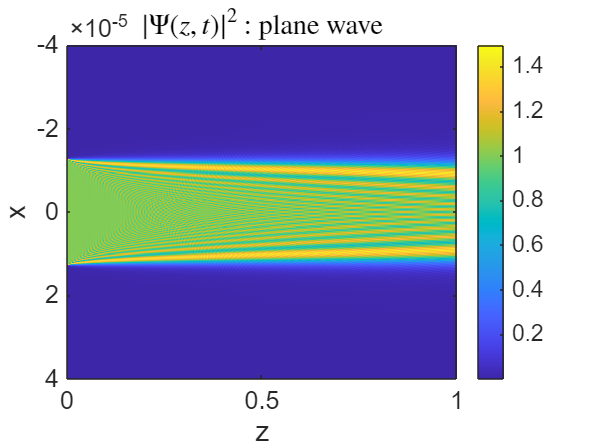

% II

hbar = [1.044e-34,1]; 
 
N = 2^16;

xmax = 8e-3;        

dx = xmax/N;

n = 0:1:(N-1); p = n;

xn = -xmax/2 + n*dx;


pmax = 2*pi*hbar(1)/dx;

dp = 2*pi*hbar(1)/xmax;

pn = -pmax/2 + p.*dp;


z_sa = 0.96;                    
z_ad = 1;                       
source_slit = 2.5e-9;          
diffract_slit = 25.4e-6;       
detector_size = 80e-6;          
lam_dB = 0.175e-10;             
m_n = 1.675e-27;                


m_k = 39*m_n;

Nz = 1000;
zend = 1;


dz = zend/Nz;
z = 0:dz:zend;
v = 2*pi*hbar(1)/m_k/lam_dB;       

dt = dz/v;

% dU = exp(-1i*pn.^2.*dt./2./m_n./hbar(1));
U = dU(dt,pn,m_k,hbar(1));



dim = 2;       

psi0_pw = rect(xn,diffract_slit);      
psi0_pw_p = ftxtop(psi0_pw,dx,hbar(1));
Psi0_pw_p = zeros(length(z),length(psi0_pw_p));
Psi0_pw_x = zeros(length(z),length(psi0_pw_p));
for zi = 1:length(z)
    dt = z(zi)./v;
    Psi0_pw_p(zi,:) = dU(dt,pn,m_k,hbar(1)).*psi0_pw_p;
    Psi0_pw_x(zi,:) = iftptox(Psi0_pw_p(zi,:),dp,hbar(1));
    % if zi == 1
    %     Psi0_pw_p(zi,:) = psi0_pw_p;
    %     Psi0_pw_x(zi,:) = iftptox(Psi0_pw_p(zi,:),dp,hbar(1));
    % else
    %     Psi0_pw_p(zi,:) = U.*Psi0_pw_p((zi-1),:);
    %     Psi0_pw_x(zi,:) = iftptox(Psi0_pw_p(zi,:),dp,hbar(1));
    % end
end

ap = (xn >= -detector_size/2 & xn <= detector_size/2);
x_limited = xn(ap);

figure;
imagesc([0,z_ad],[-detector_size/2, detector_size/2],abs(Psi0_pw_x(:,ap)').^2);
set(gca,'FontSize',15);
xlabel('z');
ylabel('x');
title('$|\Psi(z,t)|^2$ : plane wave',Interpreter='latex');
colormap parula;
colorbar;

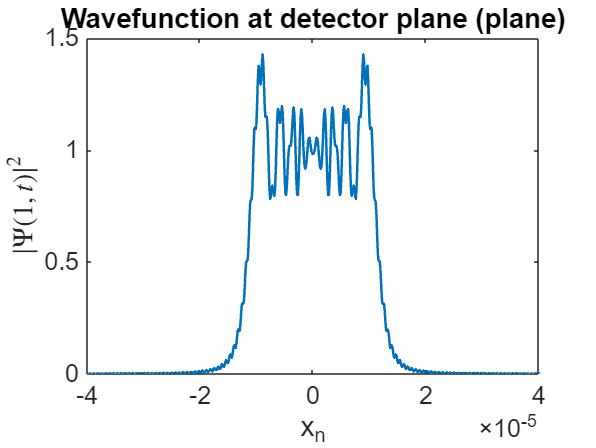



figure;
plot(xn,abs(Psi0_pw_x(end,:)).^2,'LineWidth',1.5);
xlabel('x_n');
ylabel('$|\Psi(1,t)|^2$',Interpreter='latex');
title('Wavefunction at detector plane (plane)');
set(gca,'FontSize',15);
xlim([-detector_size/2,detector_size/2]);

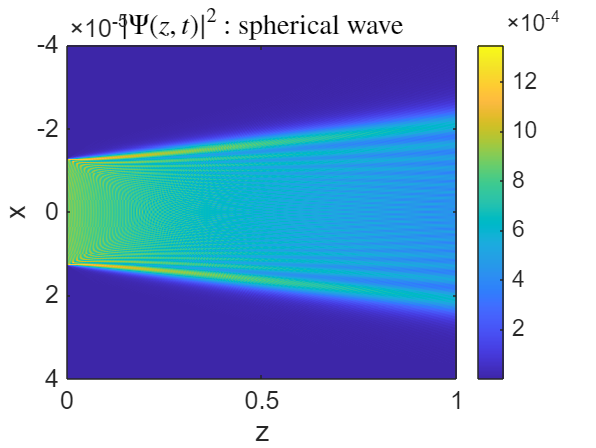



slit = rect(xn,diffract_slit);

dt = z_sa/v;

psi0source = rect(xn,source_slit);
psi0spherical = slit.*iftptox(dU(dt,pn,m_k,hbar(1)).*ftxtop(psi0source,dx,hbar(1)),dp,hbar(1));

psi0spherical_p = ftxtop(psi0spherical,dx,hbar(1));
Psi0spherical_p = zeros(length(z),length(psi0spherical_p));
Psi0spherical_x = zeros(length(z),length(psi0spherical_p));
for zi = 1:length(z)
    dt = z(zi)./v;
    Psi0spherical_p(zi,:) = dU(dt,pn,m_k,hbar(1)).*psi0spherical_p;
    Psi0spherical_x(zi,:) = iftptox(Psi0spherical_p(zi,:),dp,hbar(1));
end

% Psi0spherical_x_limited = Psi0spherical_x(:,((-detector_size/2 <= xn) && (xn <= detector_size/2)));

figure;
imagesc([0,z_ad],[-detector_size/2, detector_size/2],abs(Psi0spherical_x(:,ap)').^2);
set(gca,'FontSize',15);
xlabel('z');
ylabel('x');
title('$|\Psi(z,t)|^2$ : spherical wave',Interpreter='latex');
colormap parula;
colorbar;

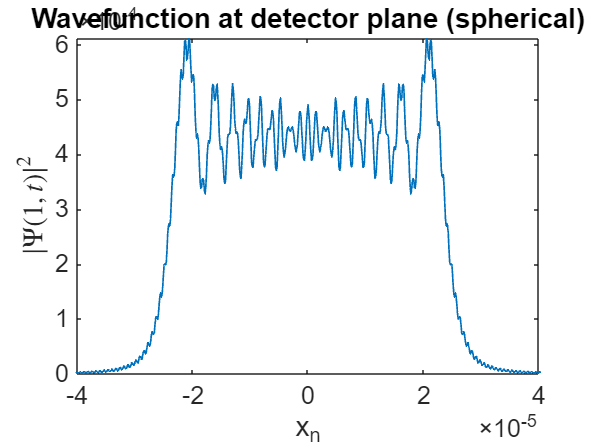



figure;
plot(xn,abs(Psi0spherical_x(end,:)).^2,'LineWidth',1);
xlabel('x_n');
ylabel('$|\Psi(1,t)|^2$',Interpreter='latex');
title('Wavefunction at detector plane (spherical)');
xlim([-detector_size/2,detector_size/2]);
set(gca,'FontSize',15);

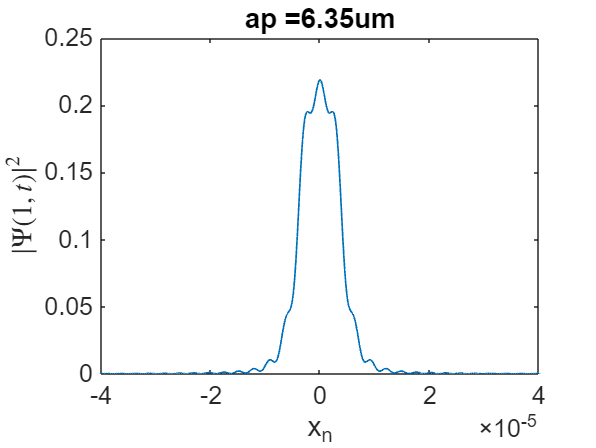



% 1. I notice how much less resolved the outputs are when I decrease the
% number of points by a factor of two, and on the other hand, how much more
% resolution I get when I increase the number of points by a factor two.
% 2. Diffraction of a spherical wave from an aperture is different than
% diffraction by an incident plane wave. Something to do with the fact that
% the wavefronts of the plane wave are flat at the aperture while the
% spherical wave has curved wavefronts.
% 3. changing the source size and aperture size
source_slit = 2.5e-6;
diffract_slit = 6.35e-6;

slit = rect(xn,diffract_slit);

dt = z_sa/v;

psi0source = rect(xn,source_slit);
psi0spherical = slit.*iftptox(dU(dt,pn,m_k,hbar(1)).*ftxtop(psi0source,dx,hbar(1)),dp,hbar(1));

psi0spherical_p = ftxtop(psi0spherical,dx,hbar(1));
Psi0spherical_p = zeros(length(z),length(psi0spherical_p));
Psi0spherical_x = zeros(length(z),length(psi0spherical_p));
for zi = 1:length(z)
    dt = z(zi)./v;
    Psi0spherical_p(zi,:) = dU(dt,pn,m_k,hbar(1)).*psi0spherical_p;
    Psi0spherical_x(zi,:) = iftptox(Psi0spherical_p(zi,:),dp,hbar(1));
end


figure;
plot(xn,abs(Psi0spherical_x(end,:)).^2,'LineWidth',1);
xlabel('x_n');
ylabel('$|\Psi(1,t)|^2$',Interpreter='latex');
title("ap =6.35um");
xlim([-detector_size/2,detector_size/2]);
set(gca,'FontSize',15);

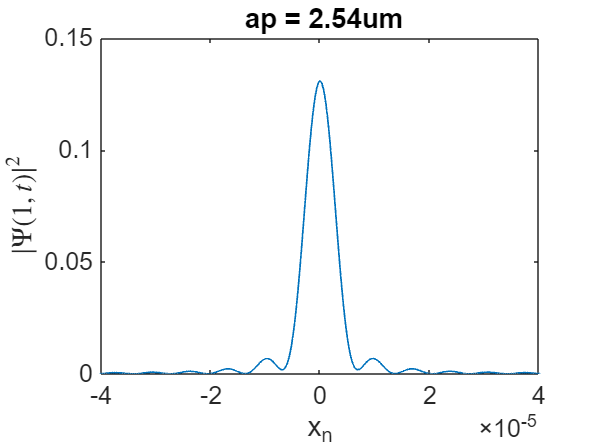



diffract_slit = 2.54e-6;
slit = rect(xn,diffract_slit);
psi0spherical = slit.*iftptox(dU(dt,pn,m_k,hbar(1)).*ftxtop(psi0source,dx,hbar(1)),dp,hbar(1));

psi0spherical_p = ftxtop(psi0spherical,dx,hbar(1));
Psi0spherical_p = zeros(length(z),length(psi0spherical_p));
Psi0spherical_x = zeros(length(z),length(psi0spherical_p));
for zi = 1:length(z)
    dt = z(zi)./v;
    Psi0spherical_p(zi,:) = dU(dt,pn,m_k,hbar(1)).*psi0spherical_p;
    Psi0spherical_x(zi,:) = iftptox(Psi0spherical_p(zi,:),dp,hbar(1));
end


figure;
plot(xn,abs(Psi0spherical_x(end,:)).^2,'LineWidth',1);
xlabel('x_n');
ylabel('$|\Psi(1,t)|^2$',Interpreter='latex');
title(" ap = 2.54um");
xlim([-detector_size/2,detector_size/2]);
set(gca,'FontSize',15);


%% movie section

% for i = 1:50
% plot(xn,abs(Psi0spherical_x(i,:)).^2,'LineWidth',1.5);
% xlabel('x_n');
% ylabel('$|\Psi(1,t)|^2$',Interpreter='latex');
% title("(spherical)"+ num2str(i));
% xlim([-detector_size/2,detector_size/2]);
% set(gca,'FontSize',15);
% 
% drawnow;
% M(i) = getframe;
% end
% movie(M,2,1)

 
function [U] = dU(dt,p,m,hbar)
    U = exp(-1i.*(p.^2).*dt./2./m./hbar);
end

function y = rect(t,bound)
    y = abs(t) <= bound/2;
    y = double(y);  
end

function [fp] = ftxtop(fx,dx,hbar)
    N  = length(fx);
    fp = dx*(1/2/pi/hbar)^(1/2)*fftshift(fft(ifftshift(fx)));
end

function [fx] = iftptox(fp,dp,hbar)
    N  = length(fp);
    fx = (N)*dp*(1/2/pi/hbar)^(1/2)*ifftshift(ifft(fftshift(fp)));
end
